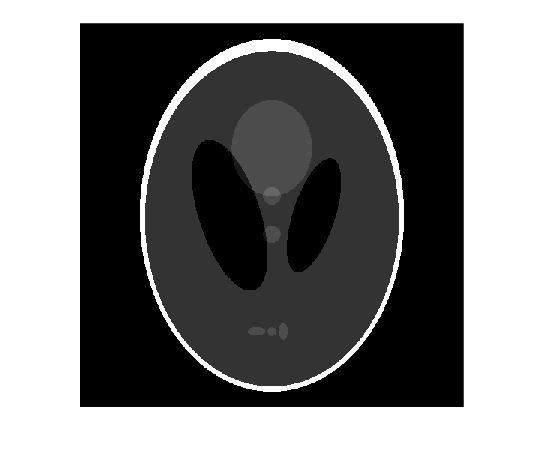

GT=phantom("Modified Shepp-Logan",512);
imshow(GT);

compressing_factor=2;

image_series=create_shifted_images(GT,compressing_factor);
compressed=compress(image_series,compressing_factor);


%[row,col]=find(compressed_shifted==0);
%super_reso=zeros(512,1024);

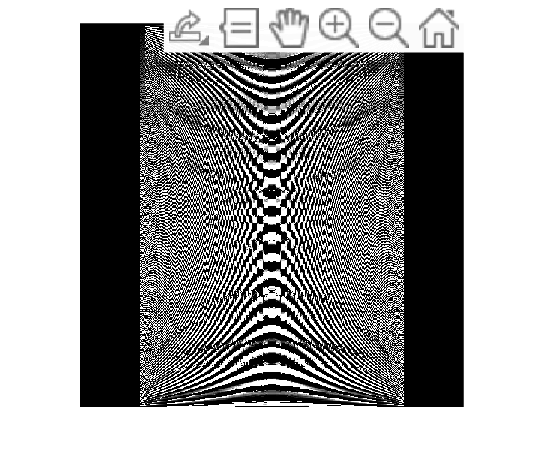

GT = phantom("Modified Shepp-Logan", 512); % Original Image
F = fft2(GT);          % Compute 2D Fourier Transform
Fshift = fftshift(F);  % Shift zero frequencies to the center

% Display Original k-Space Magnitude
figure;
subplot(2,1,1);
imshow(log(1 + abs(Fshift)), []);
title('Original k-Space Magnitude');

GT_rotated = imrotate(GT, 30, 'bilinear', 'crop'); % Rotate image by 30 degrees
F_rot = fft2(GT_rotated); % Compute Fourier Transform of rotated image
Fshift_rot = fftshift(F_rot);

subplot(2,1,2);
imshow(log(1 + abs(Fshift_rot)), []);
title('Rotated k-Space (30°)');